# Model and AutoRepo structures

This demo presents an overview of the *Model* and *AUTORePO* structures. Moreover, we introduce how to include the XPPLORE utilities in your *.m* file and how to visualize a 1P-BD with this tool. The model used for this example is the standard Hodgkin and Huxley model [1]. The ODEs of the system are the followings,

$\begin{array}{l}
c\dot{v} =I_0 +I_s \left(t\right)-I_{\textrm{Na}} \left(v,m,h\right)-I_K \left(v,n\right)-I_L \left(v\right),\\
\;\dot{m} =\alpha_m \left(v\right)\left(1-m\right)-\beta_m \left(v\right)m,\\
\;\dot{h} =\alpha_h \left(v\right)\left(1-h\right)-\beta_h \left(v\right)h,\\
\;\dot{n} =\alpha_{n\;} \left(v\right)\left(1-n\right)-\beta_n \left(v\right)n\ldotp 
\end{array}$   (1)

For more details reagarding this system, the reader should refer to [1]. The `.ode` file that we are going to use for this demo is a modified version of the one that you can find among the documentation of XPPAUT [2].

[1] Hodgkin AL, Huxley AF. *A quantitative description of membrane current and its application to conduction and excitation in nerve*. The Journal of Physiology, 1952.

[2] B Ermentrout. *Simulating, Analyzing, and Animating Dynamical Systems: A Guide to XPPAUT for Researchers and Students. *SIAM, 2002.

## ENVIRONMENT

These three commands are commonly used at the beginning of a MATLAB script to initialize the environment and ensure no leftover data, figures, or text interfere with the current execution.

clear all; close all; clc;

## XPPLORE UTILITIEs

The following commands are utilized to import all functions within the XPPLORE package. The functions designed for visualization purposes are located in the *Function_Visualization* folder, while those intended for handling and parsing XPPAUT files are stored in the *Function_XPPAUT* folder.

% IMPORT
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

Everytime, before loading any XPPAUT's output, you have to extract some information from the *.ode* file where your model is implemented. The function *Func_ReadModel* is used to retrieve the necessary information required to parse the *.auto* and the *.dat* files. 

% MODEL
M = Func_ReadModel('hh.ode');

The output of this function is a structure of structures. The **M** structure fields are **V**, **P**, and **S** as it can be seen below.

M

M = struct with fields:
    V: [1×1 struct]
    P: [1×1 struct]
    S: [1×1 struct]


**V**: This letter refers to "*Variables*" and is itself a structure. It contains, as its subfields, the dynamical and auxiliary variables defined within the `.ode` file. Each subfield can take one of the following values: {**T**, **D**, **A**}. Specifically: **T** represents the temporal variable, **D** indicates a dynamical variable and finally **A** refers to an auxiliary variable.

M.V

ans = struct with fields:
       t: 'T'
       v: 'D'
       m: 'D'
       h: 'D'
       n: 'D'
     ina: 'A'
      ik: 'A'
      il: 'A'
    stim: 'A'


**P**: It stands for *Parameters *and is a structure. Its subfields correspond to the parameters specified in the `.ode` file. Instead, their values correspond to the default parameter value implemented in the `.ode` file.

M.P

ans = struct with fields:
      i0: 0
     vna: 50
      vk: -77
      vl: -54.3870
     gna: 120
      gk: 36
      gl: 0.3000
       c: 1
     phi: 1
    iapp: 0
     ton: 100
    toff: 200
      nP: 12


**S**: It stands for *Settings. *It is a structure as well. The name of its subfields correspond to the settings declared explicitly in the `.ode` file through the "`@`" statement.

M.S

ans = struct with fields:
    bound: '10000'
    total: '500'


## AUTORePO STRUCTURE

After having parsed the implemented model, we are ready to load the AUTO calculations. We suggest to save them in a variable called **AR** to remind you that you are working with generic continuation results produced through AUTO. Otherwise, you could use the name you like the most.

To load the results, we need to use the function *Func_ReadAutoRepo*. This function requires two mandatory inputs and two optional parameters which are not presented in this demo. These are the following,

- **M**: Model structure (Structure created by using the function *Func_ReadModel*)

- **Path**: Path to the *.auto* file you want to load and explore.

- [LABELLEDPOINT*s*]: Boolean value to enable/disable the loading of the labelled points.

- [*TRAJECTORIEs*]: Boolean value to control the loading of the special trajectories.

If you want to have further details on the optional fields, you can refer to the official documentation and other more advanced examples. In the same folder where this `.mlx` file is located, you should have the `hh.auto` file*. *This file contains the results of the computation of a 1P-BD by using the applied current ($I_0$) in system (1) as the main bifurcation parameter.

% AUTOREPO
AR = Func_ReadAutoRepo(M,'hh.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_i0 - Main: i0


As you can see, the function *Func_ReadAutoRepo *prints in the command window (in this case directly after the chunk of code) the operation that it is executing and their status. Moreover, it prints a summary relative to the detected bifurcation diagrams during the parsing of the `.auto` file. In this case, the `.auto` file contains a single 1P-BD computed by using `i0` as the main bifurcation parameter. 

Before exploring the bifurcation diagram, we illustrate the organization of the AUTORePO (`AR`) structure. This latter presents the following fields, namely **SET**, **P** and (in this case) **BD1_i0** (as it was declared in the introductory section).

AR

AR = struct with fields:
       SET: [1×1 struct]
         P: [1×1 struct]
    BD1_i0: [1×1 struct]


**SET**: It is a structure with multiple fields. These are:

- **NPTS**: Number of the points calculated and stored in the current `AR` structure.

- **NUM**: Structure containing all the numerical settings under the *Numerics* menu of AUTO. Please keep in mind that, all the fields are populated with the numerical settings used during the last run computation before exporting the *.auto *file.

- **UZ**: User-defined conditions used to label extra-points during the continuation. In this case it is empty {} beacuse no user-defined conditions during the computation were set.

AR.SET

ans = struct with fields:
    NPTS: 2048
     NUM: [1×1 struct]
      UZ: {}


**P:** Hot parameters structure. It presents a number of fields equal to the number of hot parameter considered in the current problem. Each field is populated with the name of a model's parameter that can be used for continuation purposes.

AR.P

ans = struct with fields:
    Par1: 'i0'
    Par2: 'vna'
    Par3: 'vk'
    Par4: 'vl'
    Par5: 'gna'
    Par6: 'gk'
    Par7: 'gl'
    Par8: 'c'


**BD1_i0**: This is the bifurcation diagram structure. It is a structure itself and it contains the following fields,

- **P**: It is a cell vector showing the main bifurcation parameter(s).

- **LABPTs**: This field is a structure, and its subfields are the labelled points detected during the parsing of the `.auto` file. Each labelled point has the name "**PTi_TYP**" where **i** is an integer between 1 and the total number of saved labelled points in the `.auto` file**. **Instead, **TYP **is a label specifying the type of considered point. The structure contains an additional field named **nPT**. This represents the number of detected labelled points in the current BD. Labelled points associated with periodic orbit or BVP presents an additional field named **PO** containing the numerical solution of the considered dynamical system computed through numerical continuation.

- **BR**: It is a structure storing the different branches of the BD calculated through continuation. Specifically, it presents different subfields named "**Bi_TYP**" where **i** indicates an integer between **1** and **nBR**. Instead, **TYP** is the type of the considered branch. As **LABPTs**, it presents the additional field **nBR** to easily access to the number of branches associated with the considered BD.

AR.BD1_i0

ans = struct with fields:
         P: {'i0'}
    LABPTs: [1×1 struct]
        BR: [1×1 struct]


For more details regarding the organization of the AUTORePO structure please refer to the documentation.

## VISUALIZATION

To visualize the content of the bifurcation diagram `BD1_i0` inside our `AR` structure, we use the function *Func_VisualizeDiagram. *This function can be used to visualize only the branches of the continuations. Specifically, it requires the following mandatory and optional inputs:

- **M**: Model structure.

- **BD**: Bifurcation diagram structure to be visualized.

- [VAR]: Cell vector of maximum three elements. Here the variables/parameters to be visualized along the *x*, *y* and eventually *z* direction must be specified.

- [OPTIONs]: Visualization setting structure. If you want to costumize your visualization settings instead of using the default ones, then create your own `opts` structure and specify it here.

In this example, we will pass the variable **M** as first, and **AR.BD1_i0** as second input arguments. Please note that we are passing the subfield **BD1_i0 **of **AR **and not the whole structure **AR**. The optionals fields VAR and OPTIONs must be specified as name-value arguments. By default, the variables visualized along the *x*, *y, *and *z* axes depends on the considered BD. In this case, we want to visualize a 1P-BD, hence over the *x-*axis, XPPLORE visualizes the main bifurcation parameter (in this case `i0`), while along the *y-*direction the first dynamical variable specified in the `.ode` file. Keep in mind that, this function visualizes only the branches of the specified bifurcation diagram and it does not visualize the labelled points. If you want to visualize these points as well, then you should use the function *Func_VisualizeLabPoints*. It accepts the same input of the previous function. In the following, we present the lines of code necessary to visualize a 1P-BD and its labelled points.  

fig = figure();

Func_VisualizeDiagram(M,AR.BD1_i0)
Func_VisualizeLabPoints(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0  200])
ylabel('$V$ [\ ]','interpreter','latex')  , ylim([-80 40])


If you want to apply a cool-style to the diagram, then you should use the function *Func_FigStyle*. This accepts the following inputs:

- **fig**: Figure object.

- [OPTIONs]: If you want to apply a costum-style to the figure, then pass as input your new options structure. Pay attention, this option structure is different from the one that can be passed to *Func_VisualizeDiagram* or *Func_VisualizeLabPoints. *In more advanced examples we will present this functionality.

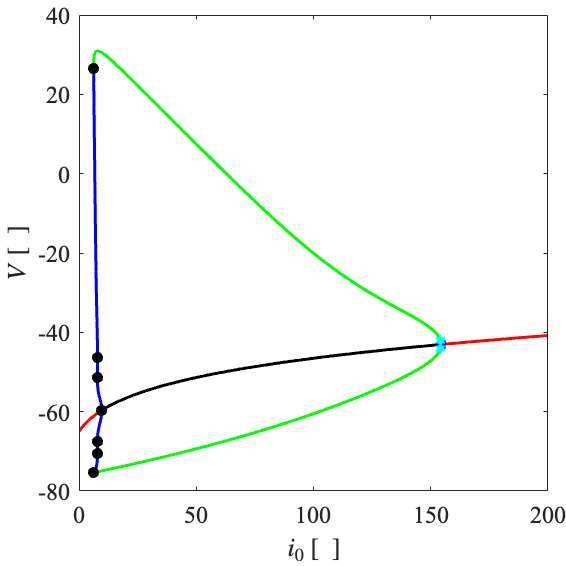

Func_FigStyle(fig)